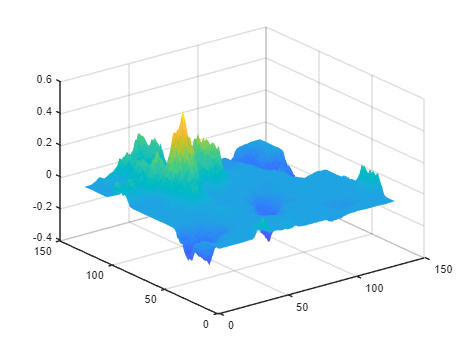

clear all
close all
clc

res = 2^7;
x = 1:res+1;
y = 1:res+1;
[X,Y] = meshgrid(x,y);
height = zeros(res+1);

p = 1; % perturbation initial value
r = 2; % change roughness (increase for smoother hills) - this is the factor perturbation decreases by each iteration
h = 1; % abs value of height range [-h h] that will be multiplied by perturbation
exp = 3; % redistribute the elevation

for i = 1:log(res)/log(2)
    sub = res/2^i;
    x_curr = 1:sub:res+1;
    y_curr = 1:sub:res+1;
    for j = 1:length(x_curr)
        for k = 1:length(y_curr)
           
            if(j == 1 || j == length(x_curr)) && (k == 1 || k == length(y_curr))
                continue
            end
            if i == 1
                height(x_curr(j),y_curr(k)) = height(x_curr(j),y_curr(k)) + p*randi([-h h]);
            end
            if i > 1
                if height(x_curr(j),y_curr(k)) == 0
                    if (mod(j,2) == 0 && mod(k,2)~=0)
                        height(x_curr(j),y_curr(k)) = (height(x_curr(j-1),y_curr(k)) + height(x_curr(j+1),y_curr(k)))/2 + p*randi([-h h]);
                    elseif (mod(j,2) ~= 0 && mod(k,2)==0)
                        height(x_curr(j),y_curr(k)) = (height(x_curr(j),y_curr(k-1)) + height(x_curr(j),y_curr(k+1)))/2 + p*randi([-h h]);
                    end
                end
            end

        end
    end

    for j = 1:length(x_curr)
        for k = 1:length(y_curr)
            if (mod(j,2) == 0 && mod(k,2)==0)
                height(x_curr(j),y_curr(k)) = (height(x_curr(j-1),y_curr(k)) + height(x_curr(j+1),y_curr(k)) + height(x_curr(j),y_curr(k-1)) + height(x_curr(j),y_curr(k+1)))/4 + p*randi([-h h]);
% height(x_curr(j),y_curr(k)) = height(x_curr(j),y_curr(k)) + p*randi([-h h]);
            end
        end
    end
    p = p/r;
end


height = real(power((height),exp));
figure
surf(x,y,height,'EdgeColor','none')


fileID = fopen('height.txt','w');

for j = 1:length(x)
    for k = 1:length(y)
        fprintf(fileID,'%d \t %d \t %.14f \n',x(j),y(k),height(j,k));
    end
end
fclose(fileID);


